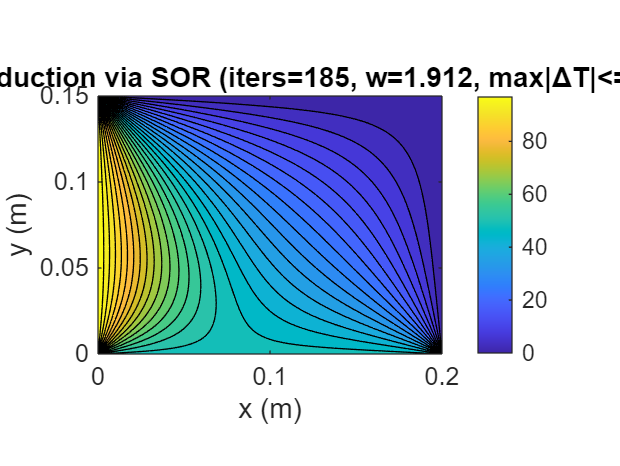

%% 2D Steady Heat Conduction via SOR (Live Script)
% Solves ∇²T = 0 (Laplace) on a rectangle with Dirichlet boundary temps.
% Feel free to tweak the parameters below and re-run this section.

%% Parameters
nx = 81;        % grid points in x  (>=3)
ny = 61;        % grid points in y  (>=3)
Lx = 0.20;      % width  [m]
Ly = 0.15;      % height [m]

T_left   = 100; % °C
T_right  = 0;   % °C
T_bottom = 50;  % °C
T_top    = 0;   % °C

tol   = 1e-5;   % convergence tolerance on max|ΔT|
maxit = 5e4;    % iteration cap

%% Grid & initialization
x = linspace(0,Lx,nx);
y = linspace(0,Ly,ny);
[X,Y] = meshgrid(x,y);   % columns=x, rows=y
dx = x(2)-x(1);
dy = y(2)-y(1);
dx2 = dx*dx; dy2 = dy*dy;
beta = dx2/dy2;

% SOR relaxation factor (near-optimal estimate)
rho = (cos(pi/(nx-1)) + cos(pi/(ny-1)))/2;
w   = 2/(1 + sqrt(max(1e-12,1 - rho^2)));
w   = min(max(w,1.05),1.95);  % clamp to a safe range

% Temperature field with boundary conditions
T = zeros(ny,nx);
T(:,1)   = T_left;
T(:,end) = T_right;
T(1,:)   = T_bottom;
T(end,:) = T_top;

% (Laplace) source term is zero
S = zeros(ny,nx);

%% Gauss–Seidel SOR iteration
denom = 2 + 2*beta;
its = 0; dmax = Inf;

while its < maxit && dmax > tol
    dmax = 0;
    for j = 2:ny-1
        for i = 2:nx-1
            rhs  = (T(j,i+1) + T(j,i-1)) + beta*(T(j+1,i) + T(j-1,i)) - dx2*S(j,i);
            Tnew = rhs / denom;
            Told = T(j,i);
            T(j,i) = (1-w)*Told + w*Tnew;
            dmax = max(dmax, abs(T(j,i)-Told));
        end
    end
    its = its + 1;
end

%% Plot result
figure('Color','w');
contourf(X,Y,T,30); colorbar
axis equal tight
title(sprintf('2D steady conduction via SOR (iters=%d, w=%.3f, max|ΔT|<=%.1e)', its, w, dmax));
xlabel('x (m)'); ylabel('y (m)');